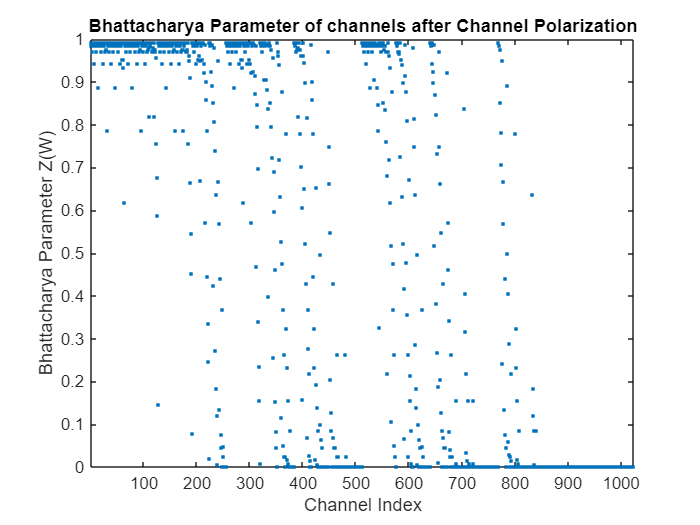

%#ok<*GVMIS>
%#ok<*NASGU>
global seq;
global index;
global f_inverse;
global ky;
f_vals=configureDictionary("double","double");
x_vals=0:0.01:200;
sz=size(x_vals);
for i=1:sz(2)
    s=round(x_vals(i)*100)/100;
    t=real(f(x_vals(i)));
    f_vals=insert(f_vals,s,t,Overwrite=false);
end
f_inverse=dictionary(values(f_vals),keys(f_vals));
N=1024;
n=log2(N);
seq=zeros(1,N);
index=1;
SNRdB=1;
SNR=10.^(SNRdB./10);
sigma_square=1/(SNR);
ky=keys(f_inverse);
temp=reli(2/sigma_square,0,n);
figure;
plot(1:N,exp(-0.25.*seq),'LineStyle','none','Marker','.');
drawnow;
xlabel('Channel Index');
ylabel('Bhattacharya Parameter Z(W)');
title('Bhattacharya Parameter of channels after Channel Polarization');
ylim([0 1]);
xlim([1 N]);

function r=reli(x,d,n)
    global seq;
    global index;
    global f_inverse;
    global ky;

    if d==n
        seq(index)=x;
        index=index+1;
        r=0;
    else 
        tempX=round(x*100)/100;
        %disp(tempX);
        val=1-(1-real(f(tempX)))^2;
        val=round(val*100)/100;
        [~,ind] = min(abs(ky-val));

        %disp(ky(ind));
        left=reli(f_inverse(ky(ind)),d+1,n);
        right=reli(2*x,d+1,n);
        r=0;
    end
end
function r=f(x)
    alpha=-0.4527;
    beta=0.0218;
    gamma=0.86;
    r=(x<=10)*exp(alpha*(x^gamma)+beta) + (x>10)*(sqrt(pi/x)*exp(-x/4)*(2-20/(7*x)))/2;
end